# ESERCITAZIONE___24/04/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI

#### Variabili Simboliche 

syms x1 x2 theta dx1 dx2 dtheta ddx1 ddx2 ddtheta u1 u2 real

#### Parametri

m1 = 1.5;
m2 = 1.0;
mp = 0.25;
l = 0.40; 
J = 0.013;
k = 35;
b = 4;
g = 9.81;

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [x1;
     x2;
     theta;
     dx1;
     dx2;
     dtheta];

% Uscita
y = [x1;
     x2;
     theta];

% Dimensioni
n = size(x,1);
m = size(u,1);
p = size(y,1);

#### Modello Dinamico Non Lineare

eq_1_sym = (m1+mp)*ddx1 + mp*l*cos(theta)*ddtheta - mp*l*sin(theta)*dtheta^2 + k*(x1-x2) + b*(dx1-dx2) == u1;
eq_2_sym = m2*ddx2 + k*(x2-x1) + b*(dx2-dx1) == u2;
eq_3_sym = (J+mp*l^2)*ddtheta + mp*l*cos(theta)*ddx1 - mp*g*l*sin(theta) == 0;

eqs_sym = [eq_1_sym;
           eq_2_sym;
           eq_3_sym];

% dx/dt
f = [dx1;
     dx2;
     dtheta;
     ddx1;
     ddx2;
     ddtheta];

% y
g = y;

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

#### Punti di Equilibrio del sistema

eq_peql = subs(eqs_sym, [dx1, dx2, dtheta, ddx1, ddx2, ddtheta, u1, u2], [0, 0, 0, 0, 0, 0, 0, 0]);

peql = solve(eq_peql, [x1, x2, theta], "ReturnConditions",true);

x_star = [peql.x1;
          peql.x2;
          peql.theta;
          0;
          0;
          0]

$$x\_star = \left(\begin{array}{c} x\\ y\\ \pi \,k\\ 0\\ 0\\ 0 \end{array}\right)$$

#### Modello Dinamico Linearizzato attorno a (x,u) = (0,0)

f_sym = solve(eqs_sym, [ddx1, ddx2, ddtheta], "ReturnConditions",true);

f = [dx1;
     dx2;
     dtheta;
     f_sym.ddx1;
     f_sym.ddx2;
     f_sym.ddtheta];

A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);


A = double(subs(A_sym, [x;u], [zeros(n,1); zeros(m,1)]));
B = double(subs(B_sym, [x;u], [zeros(n,1); zeros(m,1)]));
C = double(subs(C_sym, [x;u], [zeros(n,1); zeros(m,1)]));
D = double(subs(D_sym, [x;u], [zeros(n,1); zeros(m,1)]));

sys = ss(A, B, C, D)


sys =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4  -22.42   22.42  -1.185  -2.562   2.562       0
   x5      35     -35       0       4      -4       0
   x6    42.3   -42.3   20.75   4.834  -4.834       0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4  0.6405       0
   x5       0       1
   x6  -1.208       0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.


eig(A)

ans =   -3.2696 + 6.7801i
  -3.2696 - 6.7801i
  -4.4989 + 0.0000i
   4.4762 + 0.0000i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i


#### Controllabilità e Osservabilità

Controllabilità

if rank(ctrb(A,B)) == n
    disp('Il sistema è completamente controllabile');
else
    disp('Il sistema NON è completamente controllabile');
end

Il sistema è completamente controllabile


Osservabilità

if rank(obsv(A,C)) == n
    disp('Il sistema è completamente osservabile');
else
    disp('Il sistema NON è completamente osservabile');
end

Il sistema è completamente osservabile


## 2)  APPROCCIO ALLA LYAPUNOV

#### Specifiche 

alpha_lmi = 5;

#### Sintesi CVX

cvx_clear
cvx_begin sdp quiet
cvx_precision high
    variable Q(n,n) symmetric
    variable L(m,n)

    minimize(0);

    subject to:
        Q >= 1e-6*eye(n);  % Q semidefinita positiva
        A*Q + Q*A' -B*L -L'*B'+ 2*alpha_lmi*Q <= -1e-6*eye(n);
cvx_end

K_LMI = L/Q;

eig(A-B*K_LMI)

ans =  -10.3658 +15.1689i
 -10.3658 -15.1689i
  -6.0522 + 1.4672i
  -6.0522 - 1.4672i
  -9.1678 + 7.6842i
  -9.1678 - 7.6842i


#### Verifica Matlab

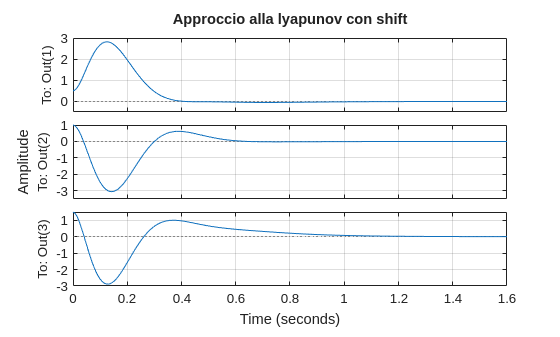

x0_lmi = [0.5;
          1.0;
          1.5;
          0;
          0;
          0];

sys_cl_lmi = ss((A-B*K_LMI), B, C, D);

figure
initial(sys_cl_lmi, x0_lmi);
grid on 
title('Approccio alla lyapunov con shift');

## 3)  ASSEGNAMENTO DEGLI AUTOVALORI

#### Specifiche

Ts = 10;
real_eig_dom = 4.6/Ts;
delta = 0.5;

x0_eig =[0.05;
         -0.05;
         deg2rad(10)];

xref = [0.15;
        0.15];

#### Sintesi 

eig_des = [-real_eig_dom, -real_eig_dom-delta, -real_eig_dom-2*delta, -real_eig_dom-3*delta, -real_eig_dom-4*delta, -real_eig_dom-5*delta];

K_eig = place(A, B, eig_des)

K_eig =   -35.3452   35.0491  -30.7112   -5.2492    4.0299   -6.3538
   33.5166  -32.5404  -27.6867    0.0434   -0.6182   -7.4202



A_cl_eig = A-B*K_eig;
eig(A_cl_eig)

ans =    -2.9600
   -0.4600
   -2.4600
   -1.9600
   -1.4600
   -0.9600


#### Compensazione del Guadagno

sys_cl_eig = ss(A_cl_eig, B, C, D);

gain = dcgain(sys_cl_eig);

N = pinv(gain)

N =    -0.3452    0.0491    0.0000
   -1.4834    2.4596   -0.0000


#### Verifica Simulazione

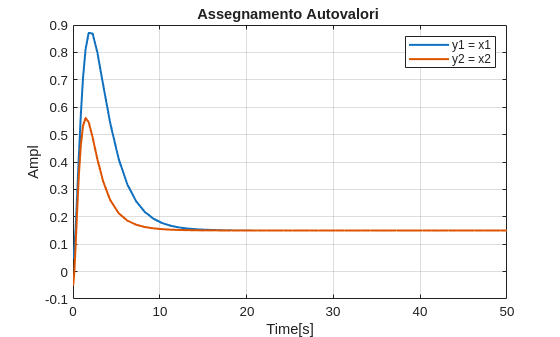

% Plot MATLAB
out = sim('EIG_24Aprile.slx');
y_eig = out.y.Data;
time = out.y.Time;

figure
plot(time, y_eig, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x2');
title('Assegnamento Autovalori ');

## 4)  CONTROLLO LQR CON AZIONE INTEGRALE 

#### Specifiche

Ts_lqr = 5;
alpha_lqr = 4/Ts_lqr;

xref_lqr = [1.0;
            1.5];

% Numero di stati da aggiungere (errori di inseguimento)
z = 2; % su x1 e x2

% Dimensione dello stato aumentato
n_aug = n+z;

#### Sistema Aumentato

C_LQR = C(1:2, :);

A_aug = [A, zeros(n,z);
         -C_LQR, zeros(z,z)];

A_hat = A_aug + alpha_lqr*eye(n_aug);

B_aug = [B;
         zeros(z,m)];

C_aug = [eye(n), zeros(n,z)];

D_aug = zeros(n,m);

sys_aug = ss(A_hat, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1     0.8       0       0       1       0       0       0       0
   x2       0     0.8       0       0       1       0       0       0
   x3       0       0     0.8       0       0       1       0       0
   x4  -22.42   22.42  -1.185  -1.762   2.562       0       0       0
   x5      35     -35       0       4    -3.2       0       0       0
   x6    42.3   -42.3   20.75   4.834  -4.834     0.8       0       0
   x7      -1       0       0       0       0       0     0.8       0
   x8       0      -1       0       0       0       0       0     0.8
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       0       0
   x4  0.6405       0
   x5       0       1
   x6  -1.208       0
   x7       0       0
   x8       0       0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   1   0   0   0   0   0   0
   y3   0   0   1   

#### Sintesi

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug +blkdiag(zeros(n), 20*eye(z))

Q =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0    20     0
     0     0     0     0     0     0     0    20


R = eye(m)

R =      1     0
     0     1


K_LQR = lqr(sys_aug, Q, R)

K_LQR =   -75.3366   33.8901 -125.3965  -34.6842    6.1916  -28.7707   17.9042    8.1812
  -38.7474   28.9309  -57.9844  -15.4701    5.7610  -13.3227   85.9955  -81.5628


K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

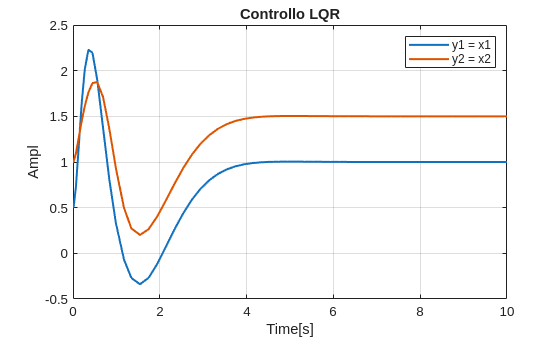

% Plot MATLAB
out = sim('LQR.slx');
y_lqr = out.y.Data;
time = out.y.Time;

figure
plot(time, y_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x2');
title('Controllo LQR');

## 5)  CONTROLLO LQG

#### Specifiche 

Qv = 1e-4*eye(n);
Rv = 1e-3*eye(m);

xref_lqg =[5.0;
           -8.5];

#### Sistema Perturbato

% Supponiamo un disturbo in ingresso su tutti gli stati
G = eye(n);

sys_perturbato = ss(A, [B G], C(1:2,:), zeros(2, size([B G],2)))


sys_perturbato =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4  -22.42   22.42  -1.185  -2.562   2.562       0
   x5      35     -35       0       4      -4       0
   x6    42.3   -42.3   20.75   4.834  -4.834       0
 
  B = 
           u1      u2      u3      u4      u5      u6      u7      u8
   x1       0       0       1       0       0       0       0       0
   x2       0       0       0       1       0       0       0       0
   x3       0       0       0       0       1       0       0       0
   x4  0.6405       0       0       0       0       1       0       0
   x5       0       1       0       0       0       0       1       0
   x6  -1.208       0       0       0       0       0       0       1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0  

#### Kalman Filter

% Guadagno di Kalman
[~, L, ~] = kalman(sys_perturbato, Qv, Rv);

A_kf = A - L*C(1:2,:);
B_kf = [B L];
C_kf = eye(n);
D_kf = zeros(size(C_kf,1), size(B_kf,2));

KF = ss(A_kf, B_kf, C_kf, D_kf)


KF =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1  -6.585  -4.585       0       1       0       0
   x2  -4.585  -3.255       0       0       1       0
   x3     179   121.1       0       0       0       1
   x4  -54.56  0.5865  -1.185  -2.562   2.562       0
   x5   11.71  -50.76       0       4      -4       0
   x6   843.5   499.9   20.75   4.834  -4.834       0
 
  B = 
           u1      u2      u3      u4
   x1       0       0   6.585   4.585
   x2       0       0   4.585   3.255
   x3       0       0    -179  -121.1
   x4  0.6405       0   32.14   21.83
   x5       0       1   23.29   15.76
   x6  -1.208       0  -801.2  -542.2
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   1   0   0   0   0
   y3   0   0   1   0   0   0
   y4   0   0   0   1   0   0
   y5   0   0   0   0   1   0
   y6   0   0   0   0   0   1
 
  D = 
       u1  u2  u3  u4
   y1   0   0   0   0
   y2   0   0   0   0
   y3   0   0   0   0
   y4   0   0   

#### Verifica Simulazione

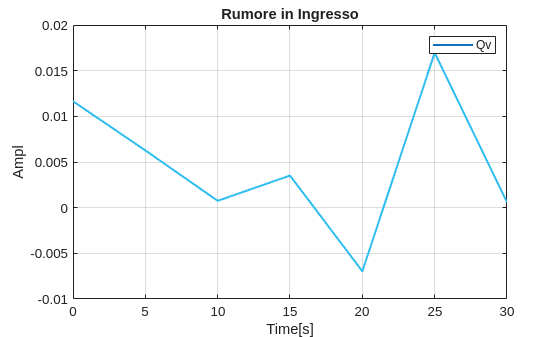

% Plot MATLAB
out = sim('LQG_24aprile.slx');
y_lqg = out.y.Data;
Rv_sim = out.Rv.Data;
Qv_sim = out.Qv.Data;
time = out.y.Time;
noise_time = out.Qv.Time;

figure
plot(noise_time, Qv_sim, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('Qv');
title('Rumore in Ingresso');

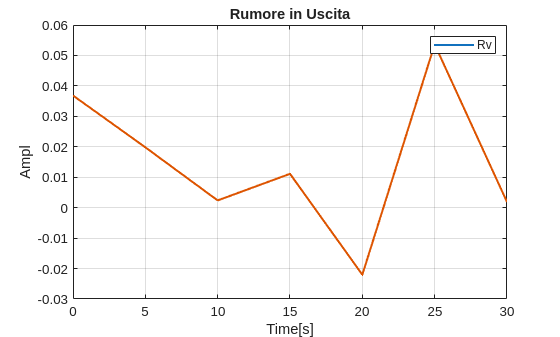


plot(noise_time, Rv_sim, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('Rv');
title('Rumore in Uscita');

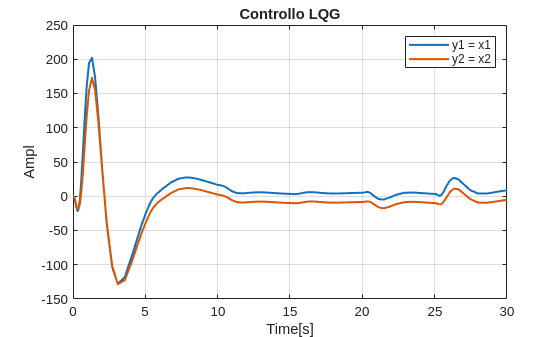


plot(time, y_lqg, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = x1', 'y2 = x2');
title('Controllo LQG');